# bisection_algorithm - Analisi di robustezza, accuratezza e prestazioni

In questo documento sono mostrati i test relativi all'algoritmo di bisezione implementato. L'accuratezza dell'algoritmo è stata misurata attraverso un confronto con la funzione `fzero` offerta dal Matlab, così come le prestazioni. Sarà mostrato che, sebbene venga garantita un'ottima accuratezza, l'algoritmo `fzero` è molto più efficiente in termini di numero di iterazioni. Dopo la valutazione delle prestazioni, sarà mostrata la metodologia applicata per effettuare i test di robustezza, con la presentazione di alcuni casi di test a scopo esemplificativo.

# Test di accuratezza

Il parametro che sarà preso come misura di riferimento è il risultato forniro dalla funzione `fzero() `offerta dal Matlab; in particolare, si utilizzerà la funzione `accuracy_bisection_algorithm()`, allegata alla documentazione, che confronta i due risultati e fornisce l'errore relativo.

f = @(x)(2-exp(-x)-sqrt(x));
x0 = [0 4];

accuracy_bisection_algorithm(f,x0,1e-10)

ans =      1.585490472710063e-11


accuracy_bisection_algorithm(f,x0,1e-11)

ans =      5.479541691557543e-12


accuracy_bisection_algorithm(f,x0,1e-12)

ans =      8.405844825501238e-13


accuracy_bisection_algorithm(f,x0,1e-13)

ans =      2.921999413876744e-14


accuracy_bisection_algorithm(f,x0,1e-14)

ans =      2.265115824710654e-16


accuracy_bisection_algorithm(f,x0,1e-15)

ans =      2.265115824710654e-16


accuracy_bisection_algorithm(f,x0,eps)

ans =      2.265115824710654e-16


# Prestazioni

Per valutare le prestazioni dell'algoritmo implementato si è preso ancora una volta come riferimento la funzione `fzero `del Matlab. In particolare, sono stati analizzati i numeri di iterazioni relativi ai due algoritmi in funzione della tolleranza richiesta: è evidente che, pur avendo raggiunto un buon grado di accuratezza, l'algoritmo implementato è molto meno efficiente della soluzione offerta da Matlab; la differenza diventa tanto più evidente quanto più aumenta il grado di risoluzione richiesta alla soluzione.

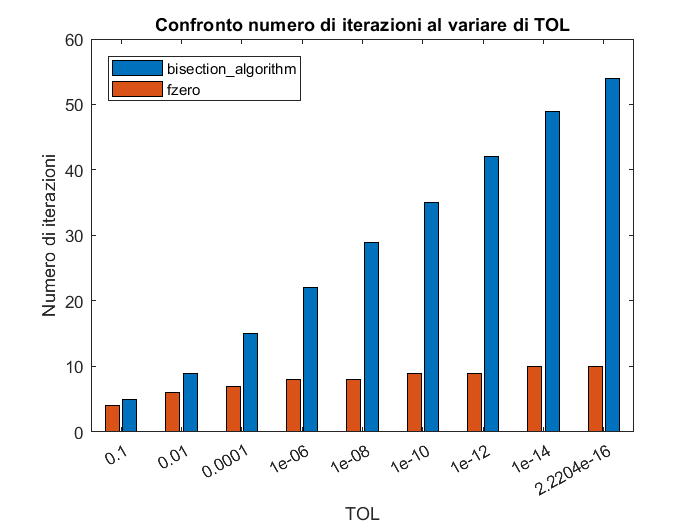

fun = @(x)(x.^2-2);
range = [0 4];
TOL=[1e-1 1e-2 1e-4 1e-6 1e-8 1e-10 1e-12 1e-14 eps];

compute_performance(fun,range,TOL);

# Test di robustezza

Per la progettazione dei casi di test è stato utilizzato il metodo di *Category-partition testing *[1], ampiamente diffuso nell'ambito dell'Ingegneria del Software per il testing funzionale. In particolare, le categorie sono state scelte in base ai parametri (di ingresso e uscita) modificabili dall'utente e in base all'ipotesi del teorema degli zeri (su cui si basa l'algoritmo); i valori sono stati scelti in base alle condizioni di errore/warning in cui ci si può venire a trovare.

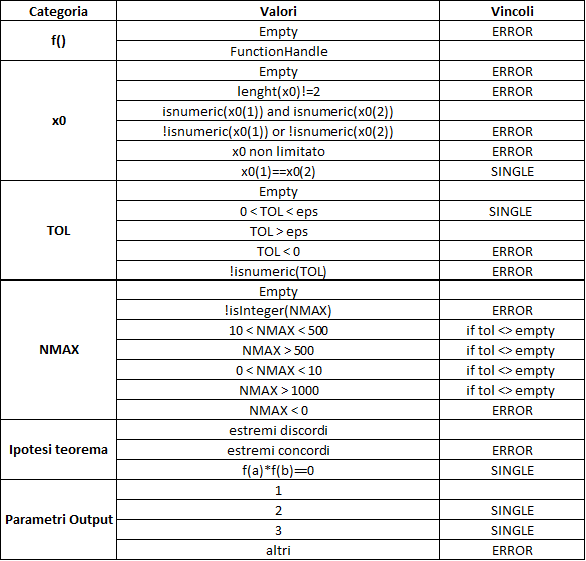

Il numero di casi di test è: 1*1*2*5*1*1 + 11 + 5 - 4 = 22. La prima somma è dovuta ai vincoli di `error`, la seconda a quelli di `single`, la sottrazione ai vincoli `property`.

Per l'implementazione dei casi di test è stato utilizzato il framework di MatLab per il testing di unità [2]*; *questa scelta ha permesso di automatizzare completamente l'esecuzione dei test: infatti, è possibile lanciare la simulazione con l'istruzione

Running test_suite
..........
..........
..
Done test_suite
__________



results =   1×22 TestResult array with properties:

    Name
    Passed
    Failed
    Incomplete
    Duration
    Details

Totals:
   22 Passed, 0 Failed, 0 Incomplete.
   1.5923 seconds testing time.


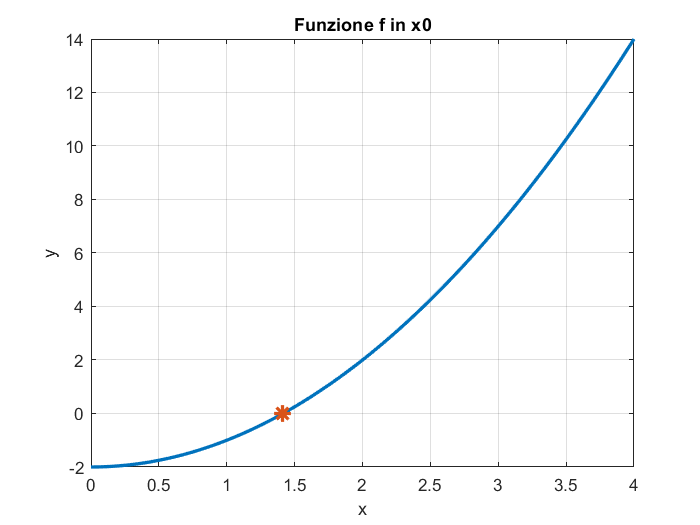

results = runtests('test_suite.m')

Il sistema esegue in automatico i test, riportando in `results `un sommario di quanti hanno avuto successo e dettagliando gli errori in quelli che eventualmente sono falliti. 

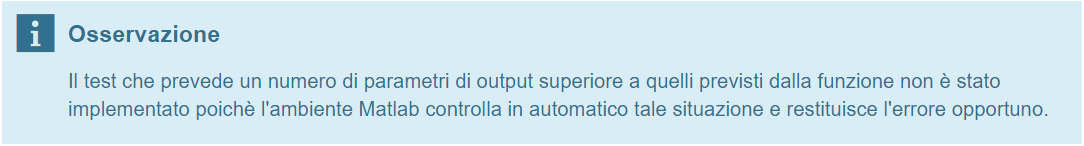

Nella maggioranza dei test sono stati usati dati comuni per cui è stata sfruttata la funzione `setup `per istanziare i dati comuni ai test case:

fun = @(x)(2-exp(-x)-sqrt(x));
range = [0 4];

Di seguito viene descritta l'implementazione di alcuni casi di test a titolo esemplificativo.

## Caso di test 1                                                                                                                         

La configurazione dei parametri è:

- `fun`: valido

- `x0`: valido

- `TOL`: vuoto

- `NMAX`: vuoto

- `ipotesi del teorema`: verificate

- `parametri di output: 1`

function testFunctionCase1(testCase)

    [fun,range] = getGlobalParameter;
    
    actSolution= bisection_algorithm(fun,range);
    expSolution= fzero(fun,range);
    
    abs_error= abs(actSolution-expSolution);
    if abs_error<= eps*max(actSolution,expSolution)
        % passed
        verifyReturnsTrue(testCase,@true);
    else
        % not passed
        verifyReturnsTrue(testCase,@false);
    end
end

Viene calcolato lo zero di `fun `sia con `bisection_algorithm `che con `fzero; `confrontando l'errore assoluto con l'epsilon associato al max dei risultati si può decidere se la risoluzione del calcolo è sufficiente.

## Caso di test 12                                                                                                                       

La configurazione dei parametri è:

- `fun`: valido

- `x0`: valido

- `TOL`: valido

- `NMAX`: not numeric

- `ipotesi del teorema`: verificate

- `parametri di output: 1`

function testFunctionCase12(testCase)  
    [fun,range] = getGlobalParameter;
    TOL = eps;
    NMAX = 'a';
    testCase.verifyError(@()bisection_algorithm(fun,range,TOL,NMAX),'bisection_algorithm:ErrorNMAX')
end

In questo caso la funzione di servizio` verifyError() `controlla che l'esecuzione del test generi un errore identificato dall'id` 'bisection_algorithm:ErrorNMAX'.`

## Caso di test 14                                                                                                                       

La configurazione dei parametri è:

- `fun`: valido

- `x0`: valido

- `TOL`: valido

- `NMAX`: 0 < NMAX < 10

- `ipotesi del teorema`: verificate

- `parametri di output: 1`

function testFunctionCase14(testCase)    
    [fun,range] = getGlobalParameter;
    TOL = eps;
    NMAX = 5;
    testCase.verifyWarning(@()bisection_algorithm(fun,range,TOL,NMAX),'bisection_algorithm:WarningMinNMAX')
end

In questo caso il sistema controlla che l'esecuzione del test generi l'appropriato warning all'utente. Non è necessario calcolare l'errore relativo della funzione poichè avendo specificato un numero ridotto di iterazione, non è possibile predire quanto sarà preciso il risultato finale.

## Caso di test 20                                                                                                                         

La configurazione dei parametri è:

- `fun`: valido

- `x0`: valido

- `TOL`: valido

- `NMAX`: 0 < NMAX < 10

- `ipotesi del teorema`: verificate

- `parametri di output: 1`

NOTA: lo zero si trova nell'estremo dell'intervallo

function testFunctionCase20(testCase)    
    fun = @(x)(x.^2 - 1);
    range = [0 1]; 
    [~,fx]= bisection_algorithm(fun,range);
    verifyEqual(testCase,fx.niter,0);
end

In questo caso non sono stati usati i parametri "globali" usati per i test precedenti. L'obiettivo del test è verificare che l'algoritmo trova subito lo zero se questo è in corrispondenza di uno degli estremi dell'intevallo passato in ingresso; tale controllo viene effettuato considerato il secondo parametro di uscita (`fx`) della funzione.

## Riferimenti                                                                                                                  

[1] *Robert D. Cameron, 2013, *[http://www.cs.sfu.ca/~cameron/Teaching/473/category-partition.html](http://www.cs.sfu.ca/~cameron/Teaching/473/category-partition.html)

[2] Matlab Documentation, [https://it.mathworks.com/help/matlab/function-based-unit-tests.html](https://it.mathworks.com/help/matlab/function-based-unit-tests.html)

## Autori                                                                                                                          

Valerio La Gatta, Marco Postiglione